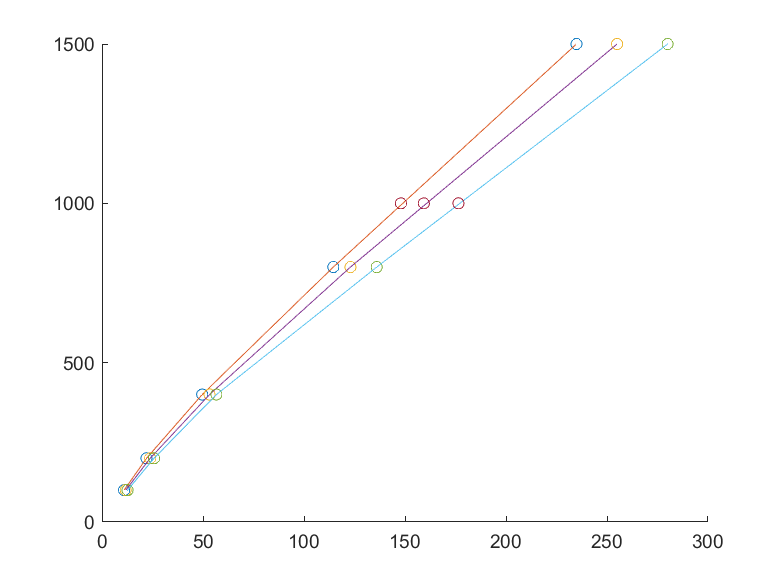

clear
t=[10.93 11.74 12.64
    22.02 23.84 25.74
    49.60 53.24 56.64
    114.5 123 136
    234.9 255 280];
s=[100 200 400 800 1500];
for ii=1:3
    hold on
    scatter(t(:,ii),s)
    plot(t(:,ii),s)
end
for ii=1:3
    syms a b c t1
    h=3;x=t(h,ii);
    eq1 = s(h)==a*x^2+b*x+c;h=h+1;
    x=t(h,ii);
    eq2 = s(h)==a*x^2+b*x+c;h=h+1;
    x=t(h,ii);
    eq3 = s(h)==a*x^2+b*x+c;
    [A(ii) B(ii) C(ii)]=solve(eq1,eq2,eq3);
    T(ii) = double(round(min(solve(1000 == A(ii)*t1^2 + B(ii)*t1 + C(ii),t1>0)),2));
    T1(ii,:) = [floor(T(ii)/60) mod(T(ii),60)];
end
scatter(T,ones(1,3)*1000)